# bg pierre

## parametre

h=1;
longueur=6;
largeur=3;
laplacien=5;
Trouge=15;
Tmarron=20;

## matrice A

A1=diag(-4*ones(4,1))+diag(ones(3,1),-1)+diag(ones(3,1),1)

A1 =     -4     1     0     0
     1    -4     1     0
     0     1    -4     1
     0     0     1    -4


A2=diag(ones(4,1))

A2 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


A=[A1 A2;
   A2 A1 ]

A =     -4     1     0     0     1     0     0     0
     1    -4     1     0     0     1     0     0
     0     1    -4     1     0     0     1     0
     0     0     1    -4     0     0     0     1
     1     0     0     0    -4     1     0     0
     0     1     0     0     1    -4     1     0
     0     0     1     0     0     1    -4     1
     0     0     0     1     0     0     1    -4


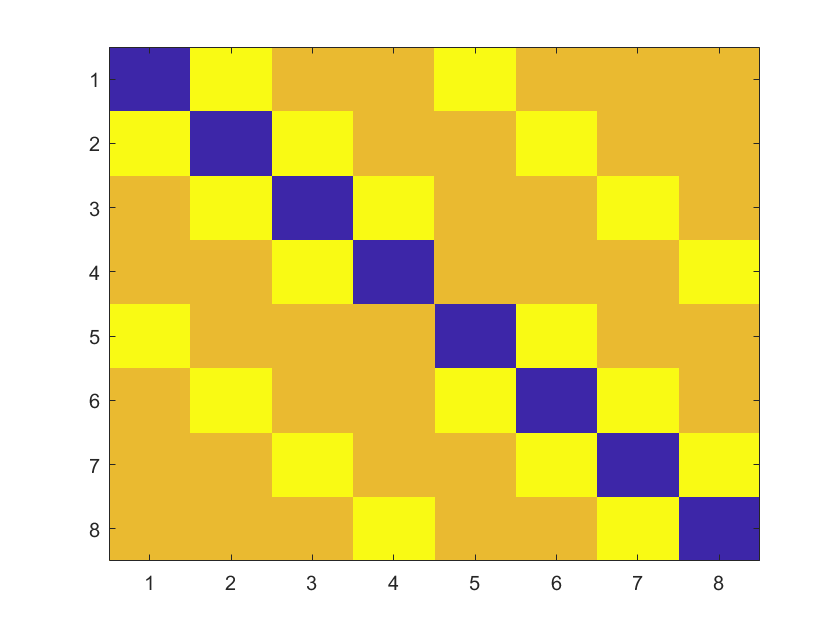

imagesc(A)

## vecteur C

C=ones(8,1)*h^2*laplacien

C =      5
     5
     5
     5
     5
     5
     5
     5


C(1,1)=C(1,1)-Trouge-Tmarron;
C(2,1)=C(2,1)-Trouge;
C(3,1)=C(3,1)-Trouge;
C(4,1)=C(4,1)-Trouge-Tmarron;
C(5,1)=C(5,1)-2*Tmarron;
C(6,1)=C(6,1)-Tmarron;
C(7,1)=C(7,1)-Tmarron;
C(8,1)=C(8,1)-2*Tmarron;
C

C =    -30
   -10
   -10
   -30
   -35
   -15
   -15
   -35


## Tvec

Tvec=A\C

Tvec =    14.8421
   13.2105
   13.2105
   14.8421
   16.1579
   14.7895
   14.7895
   16.1579


## matrice finale Z

Z=zeros(4,6)

Z =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


for i=2:3
    Z(i,2:5)=Tvec(1+(i-2)*4:4+(i-2)*4,1);
end
Z

Z =          0         0         0         0         0         0
         0   14.8421   13.2105   13.2105   14.8421         0
         0   16.1579   14.7895   14.7895   16.1579         0
         0         0         0         0         0         0


Z(:,1)=Tmarron;
Z(:,6)=Tmarron;
Z(4,:)=Tmarron;
Z(1,:)=Trouge

Z =    15.0000   15.0000   15.0000   15.0000   15.0000   15.0000
   20.0000   14.8421   13.2105   13.2105   14.8421   20.0000
   20.0000   16.1579   14.7895   14.7895   16.1579   20.0000
   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000


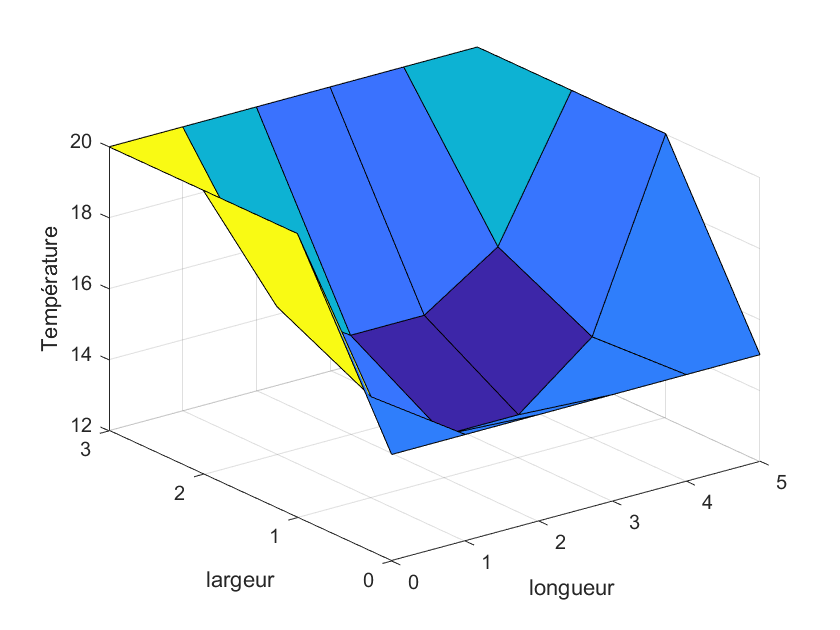


figure(1)
[xq,yq]=meshgrid(0:5,0:3);
surf(xq,yq,Z)
xlabel('longueur')
ylabel('largeur')
zlabel('Température')

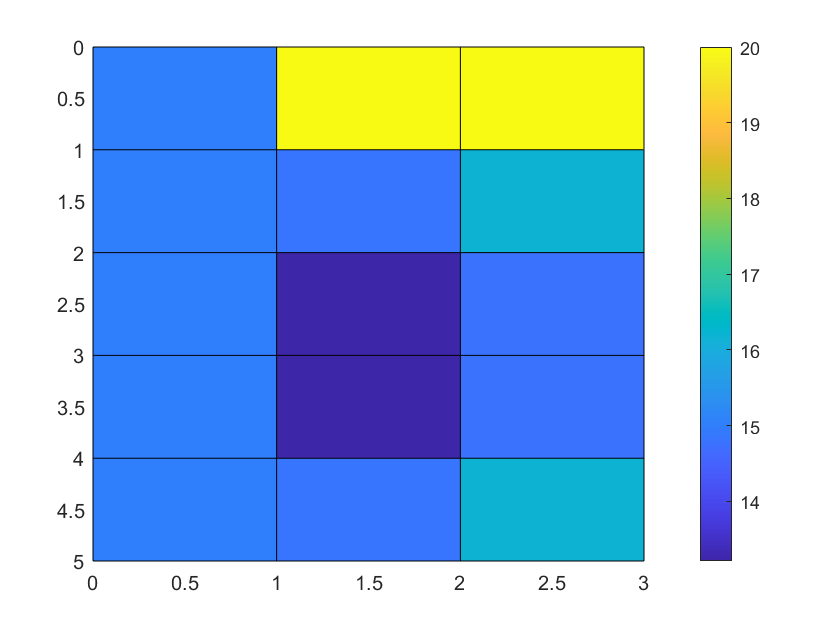


figure(2)
surf(xq,yq,Z)
view([90,90])
colorbar


figure(3)
[xqq,yqq] = meshgrid(0:.1:5, 0:.1:3); %précision d'interpolation
vq = griddata(xq,yq,Z,xqq,yqq,'cubic')

vq =    15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000
   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   1

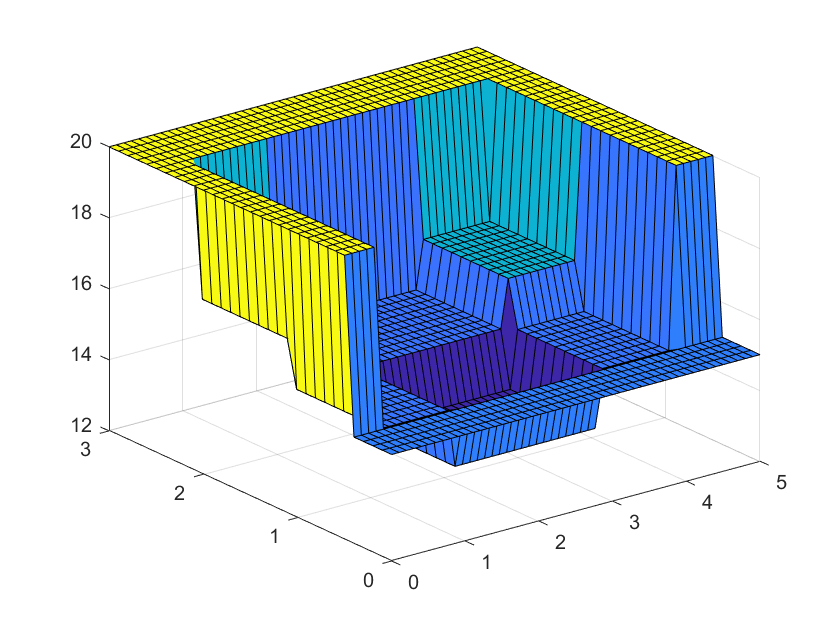

surf(xqq,yqq,vq)